syms s t

g = 2*sin(3*t)*cos(5*t)

$$g = 2\,\cos\left(5\,t\right)\,\sin\left(3\,t\right)$$

Wo = k_avg/(Tm_avg*s^2+s)

$$Wo = \frac{32}{125\,\left(\frac{s^{2}}{20}+s\right)}$$

[WoNum, WoDen] = numden(Wo)

$$WoNum = 128$$

$$WoDen = 25\,s^{2}+500\,s$$

[WgNum, WgDen] = numden(laplace(g))

$$WgNum = 6\,s^{2}-96$$

$$WgDen = \left(s^{2}+4\right)\,\left(s^{2}+64\right)$$

syms c c0
WrDen = c * WgDen * (s+c0)

$$WrDen = c\,\left(s^{2}+4\right)\,\left(s^{2}+64\right)\,\left(c_{0}+s\right)$$

syms c1 c2 c3 c4 c5 c6
WrNum = c1*s^5 + c2*s^4 + c3*s^3 + c4*s^2 + c5*s + c6

$$WrNum = c_{1}\,s^{5}+c_{2}\,s^{4}+c_{3}\,s^{3}+c_{4}\,s^{2}+c_{5}\,s+c_{6}$$

pol = coeffs(WrNum*WoNum+ WrDen*WoDen, s, 'All')

$$pol = \left(\begin{array}{cccccccc} 25\,c & 500\,c+25\,c\,c_{0} & 1700\,c+128\,c_{1}+500\,c\,c_{0} & 34000\,c+128\,c_{2}+1700\,c\,c_{0} & 6400\,c+128\,c_{3}+34000\,c\,c_{0} & 128000\,c+128\,c_{4}+6400\,c\,c_{0} & 128\,c_{5}+128000\,c\,c_{0} & 128\,c_{6} \end{array}\right)$$

polaa = WrNum*WoNum+ WrDen*WoDen

$$polaa = 128\,c_{6}+128\,c_{5}\,s+128\,c_{1}\,s^{5}+128\,c_{2}\,s^{4}+128\,c_{3}\,s^{3}+128\,c_{4}\,s^{2}+c\,\left(s^{2}+4\right)\,\left(s^{2}+64\right)\,\left(c_{0}+s\right)\,\left(25\,s^{2}+500\,s\right)$$

neededPol = coeffs((s+1)*(s+1)*(s+1)*(s+1)*(s+1)*(s+1)*(s+1), s, 'All')

$$neededPol = \left(\begin{array}{cccccccc} 1 & 7 & 21 & 35 & 35 & 21 & 7 & 1 \end{array}\right)$$

sol = solve(pol == neededPol)

sol = struct with fields:
     c: 1/25
    c0: -13
    c1: 213/128
    c2: -441/128
    c3: 17459/128
    c4: -1771/128
    c5: 66567/128
    c6: 1/128



WrNumSol = sym2poly(subs(WrNum, [c c0 c1 c2 c3 c4 c5 c6], [sol.c sol.c0 sol.c1 sol.c2 sol.c3 sol.c4 sol.c5 sol.c6]))

WrNumSol =     1.6641   -3.4453  136.3984  -13.8359  520.0547    0.0078


WrDenSol = sym2poly(subs(WrDen, [c c0], [sol.c sol.c0]))

WrDenSol =     0.0400   -0.5200    2.7200  -35.3600   10.2400 -133.1200



simtime = 40;
first = sim("Task2spec.slx", simtime)

first =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                      g: [1x1 timeseries] 
                   tout: [209x1 double] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


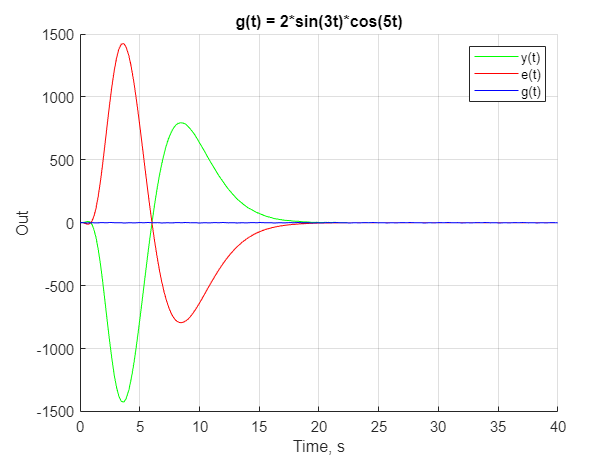

hold on
plot(first.y.Time, first.y.Data, 'green')
plot(first.e.Time, first.e.Data, 'red')
plot(first.g.Time, first.g.Data, 'blue')

xlabel("Time, s")
ylabel("Out")
grid on
title('g(t) = 2*sin(3t)*cos(5t)')
legend("y(t)", "e(t)", "g(t)")